data = readtable('20SiCp.xlsx');
data.Properties.VariableNames = {'Strain','Strain Rate','T1','T2','T3','T4','T5'}

data = 5×7 table
    Strain    Strain Rate     T1       T2       T3       T4      T5 
    ______    ___________    _____    _____    _____    ____    ____

     NaN           NaN         300      350      400     450     500
     0.5         0.001       118.6     77.5     38.2      26       7
     0.5          0.01       170.9    103.8     63.5    37.5      15
     0.5           0.1       233.1    141.2     88.9    57.6    24.1
     0.5             1       291.1    177.8    120.6    83.1    45.5


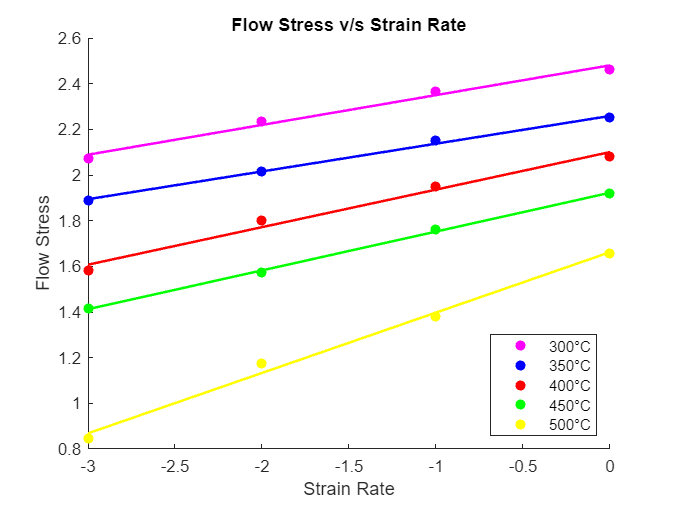

data(1,:)=[];

datan= table2array(data);
% 0.1 strain
strain_1 = datan(1:4,2:end);
sr1 = strain_1(:,1);
strainlog = log10(sr1);
stress1 = strain_1(:,2:end);y = zeros(4,5);
stresslog = log10(stress1);
C = {'m','b','r','g','y'};
hold on
for r = 1:length(stress1)
Scatter(r) =scatter(strainlog,stresslog(:,r),'filled','MarkerFaceColor',C{r});
c= polyfit(log10(sr1),log10(stress1(:,r)),1);
y(:,r) = polyval(c,log10(sr1));
plot(log10(sr1),y(:,r),'LineWidth',1.5,'Color',C{r})
end
ylabel('Flow Stress');xlabel('Strain Rate');
title('Flow Stress v/s Strain Rate')
legend(Scatter,'300°C','350°C','400°C','450°C','500°C','Location','southeast');
hold off

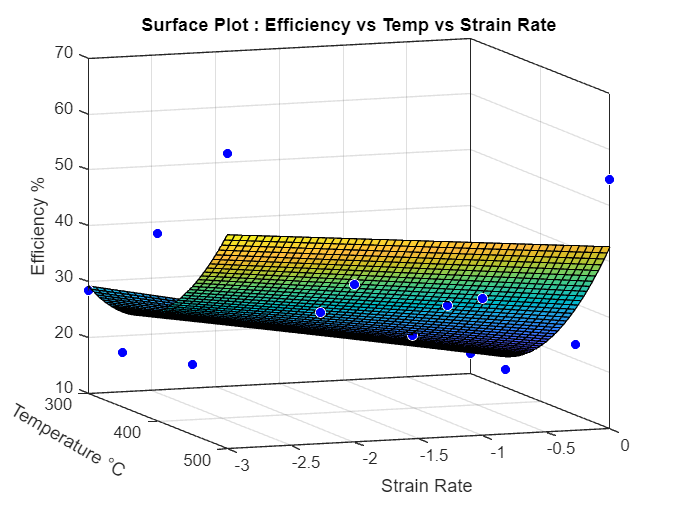


%slope or strain rate sensitivity
m= zeros(4,length(stress1));
for k = 1:length(stress1)
for p = 1:4
c1= polyfit(log10(sr1),log10(stress1(:,k)),3);
deriv = polyder(c1);
m(p,k) = polyval(deriv,strainlog(p));
end
end
e= (2*m./(m+1))*100;
T= 300:50:500;

%instability zone
e1= e/200;
slope= zeros(4,length(stress1));
for k = 1:length(stress1)
for p = 1:4
c2= polyfit(log10(sr1),log10(e1(:,k)),3);
deriv = polyder(c2);
slope(p,k) = polyval(deriv,strainlog(p));
end
end
iz = slope +m;

%% Fit: 'untitled fit 1'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, e );
% Set up fittype and options.
ft = fittype( 'poly21' );
% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );
% Make contour plot.
figure( 'Name', 'Power Dissipation' );
h = plot( fitresult, [xData, yData], zData, 'Style', 'Surface' );
% Label axes
xlabel( 'Temperature °C ', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
grid on
zlabel('Efficiency %')
view([70 10]);
set(get(gca,'xlabel'), 'Rotation',-30);
title('Surface Plot : Efficiency vs Temp vs Strain Rate');

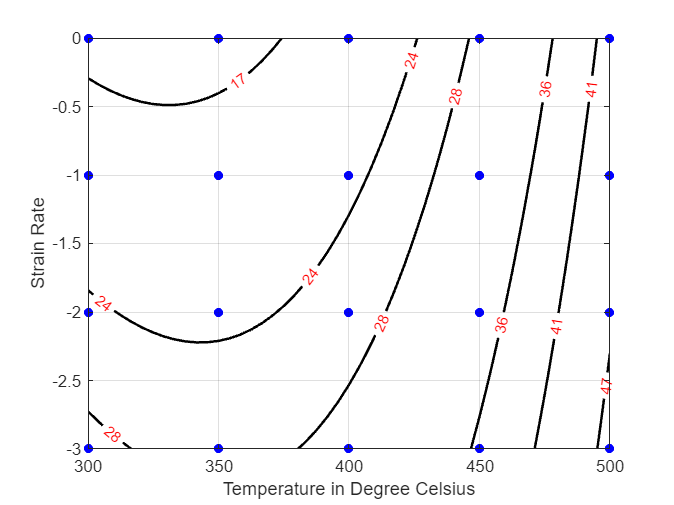


%% Fit: 'untitled fit 1'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, e );

% Set up fittype and options.
ft = fittype( 'poly21' );
% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );
% Make contour plot.
figure( 'Name', 'Power Dissipation' );
h = plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
grid on
clabel(h(1).ContourMatrix, h(1),'FontSize',9,'Color','Red');
set(h(1),'LineWidth',1.5,'Fill','off');
set(h(1),'LevelList',[13,17,24,28,36,41,47,53,58,64,71,75])

fig = gcf;
saveas(gcf,'pd0_5.jpg')

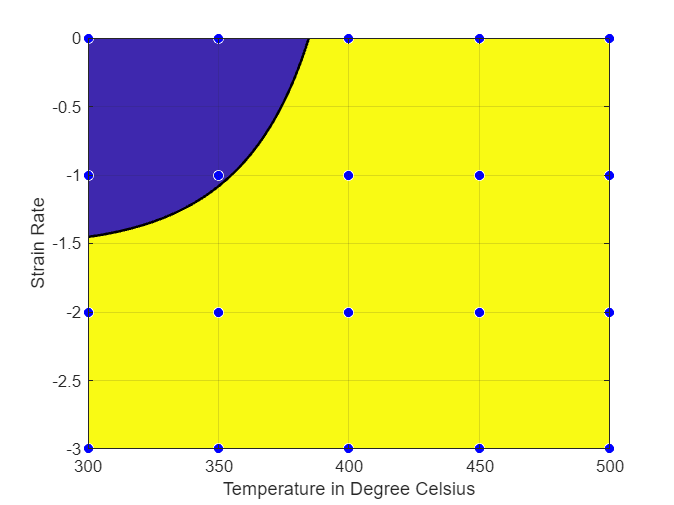


%% Fit: 'untitled fit 2'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, iz );

% Set up fittype and options.
ft = fittype( 'poly21' );
% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );
% Make contour plot.
figure( 'Name', 'untitled fit 2' );
w=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );

ylabel( 'Strain Rate', 'Interpreter', 'none' );
grid on
set(w(1),'LineWidth',1.5,'LevelStep',2);
fig = gcf;
saveas(gcf,'is0_5.jpg')

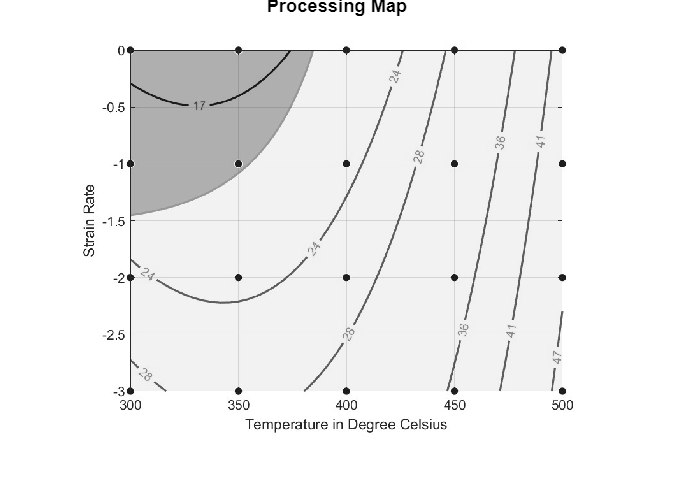


% BASIC IMAGE PROCESSING : SUPERIMPOSE
fig1 = imread('pd0_5.jpg');
fig2 = imread('is0_5.jpg');
fusionimage=imfuse(fig1,fig2,'falsecolor','Scaling','joint');
op=rgb2gray(fusionimage);
imshow(op);
title('Processing Map')